# **Introductory script illustrating aspects of the TreeShrew cone mosaic**

*This script illustrates how to create the default and customized TreeShrew cone mosaics.*

*Copyright: Nicolas P. Cottaris,  ISETBio Team, 2018*

# **Step 1.** Create and visualize the default TreeShrew cone mosaic

% Start by generating the default tree shew optics. 
% We need to do this because we need to obtain the microns/deg 
% conversion factor for the treeshrew retina, which depends on 
% the focal length of the treeshrew eye.
tOptics = opticsTreeShrewCreate();
umPerDegOnTreeShrewRetina = tOptics.micronsPerDegree;

% Generate the default cone mosaic
tDefaultMosaic = coneMosaicTreeShrewCreate(umPerDegOnTreeShrewRetina);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 256
Scones after making an S-cone free central patch: 256 (added Lcones:0, added Mcones:0)
Scones after pass 1: 150 (added Lcones:140, added Mcones:0)
Scones after pass 2: 92 (added Lcones:89, added Mcones:0)
Scones after pass 3: 56 (added Lcones:47, added Mcones:0)
Scones after pass 4: 46 (added Lcones:10, added Mcones:0)
Scones after pass 5: 46 (added Lcones:0, added Mcones:0)



% Display some info on the mosaic
tDefaultMosaic.displayInfo()


Mosaic info:
                                      Size (microns): 158.0 (w) x 158.0 (h)
                                           FOV (deg): 2.08 (w) x 2.08 (h)
                                   Retinal coverages: 0.775 (aperture) x 0.890 (geometric)
                              Grid resampling factor: 7
                   Cone geometric aperture (microns): 6.65 (w) x 6.65 (h), diameter: 7.50
             Cone light colleting aperture (microns): 6.20 (w) x 6.20 (h), diameter: 7.00

                     Cone geometric area (microns^2): 44.1786 
               Cone light colleting area (microns^2): 38.4845
                                    Rectangular grid: 20 cols x 20 rows
                                      Resampled grid: 553 cols x 553 rows
                                         Total cones: 305809
                                        Active cones: 513
                                            L- cones: 467 (91.033%)
                                            M- con

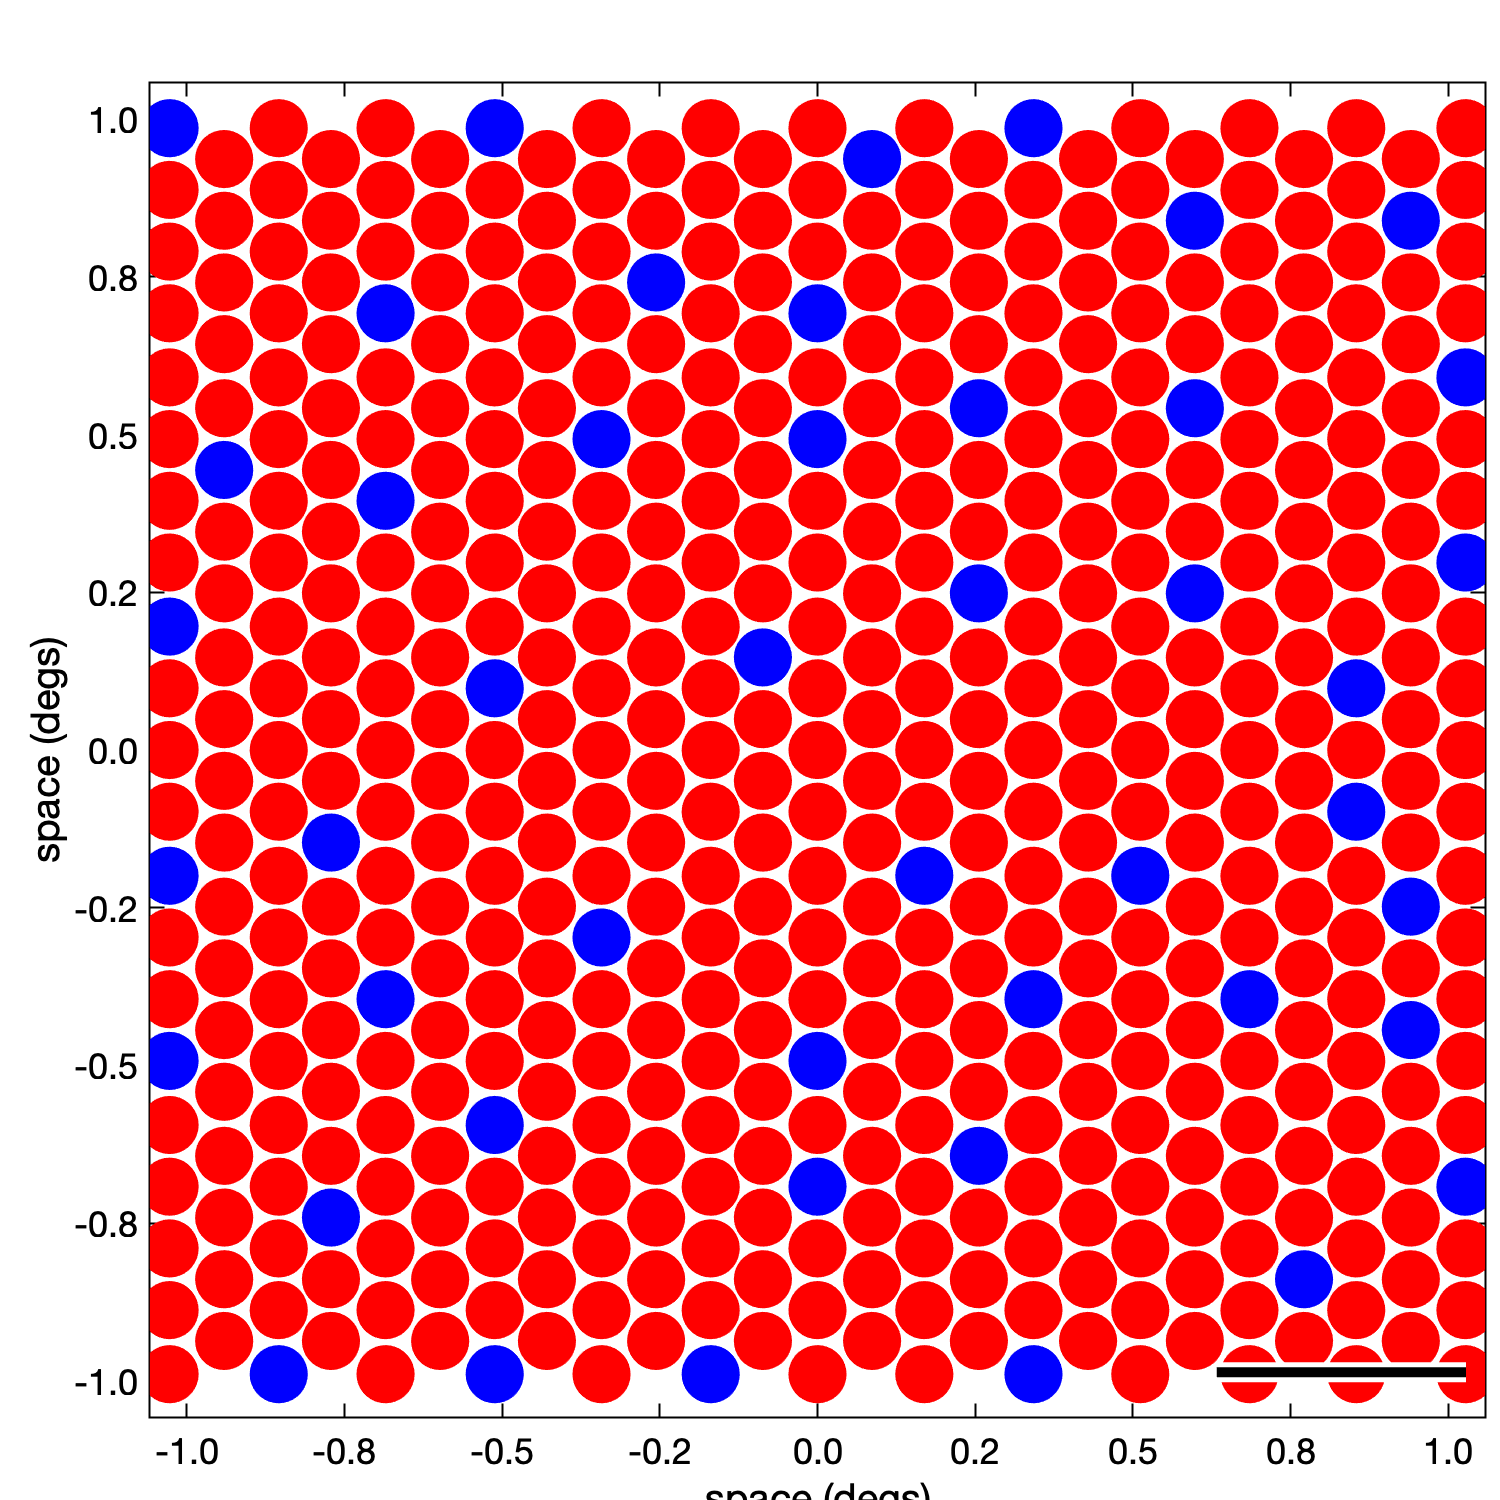


% Visualize the mosaic along with a 30-micron scale bar
tDefaultMosaic.visualizeGrid(...
    'backgroundColor', [1 1 1], ...
    'generateNewFigure', true, ...
    'scaleBarLengthMicrons', 30, ...
    'ticksInVisualDegs', true);

For comparison, the following figure depicts an S-cone stained whole-mount retina of the TreeShrew (*Figure 3 from Muller et al (1989) "Opsin and S-antigen-like immunoreactions in photoreceptors of the Tree Shrew retina"*). The scale bar is 30 microns, like in the ISETBio figure above.

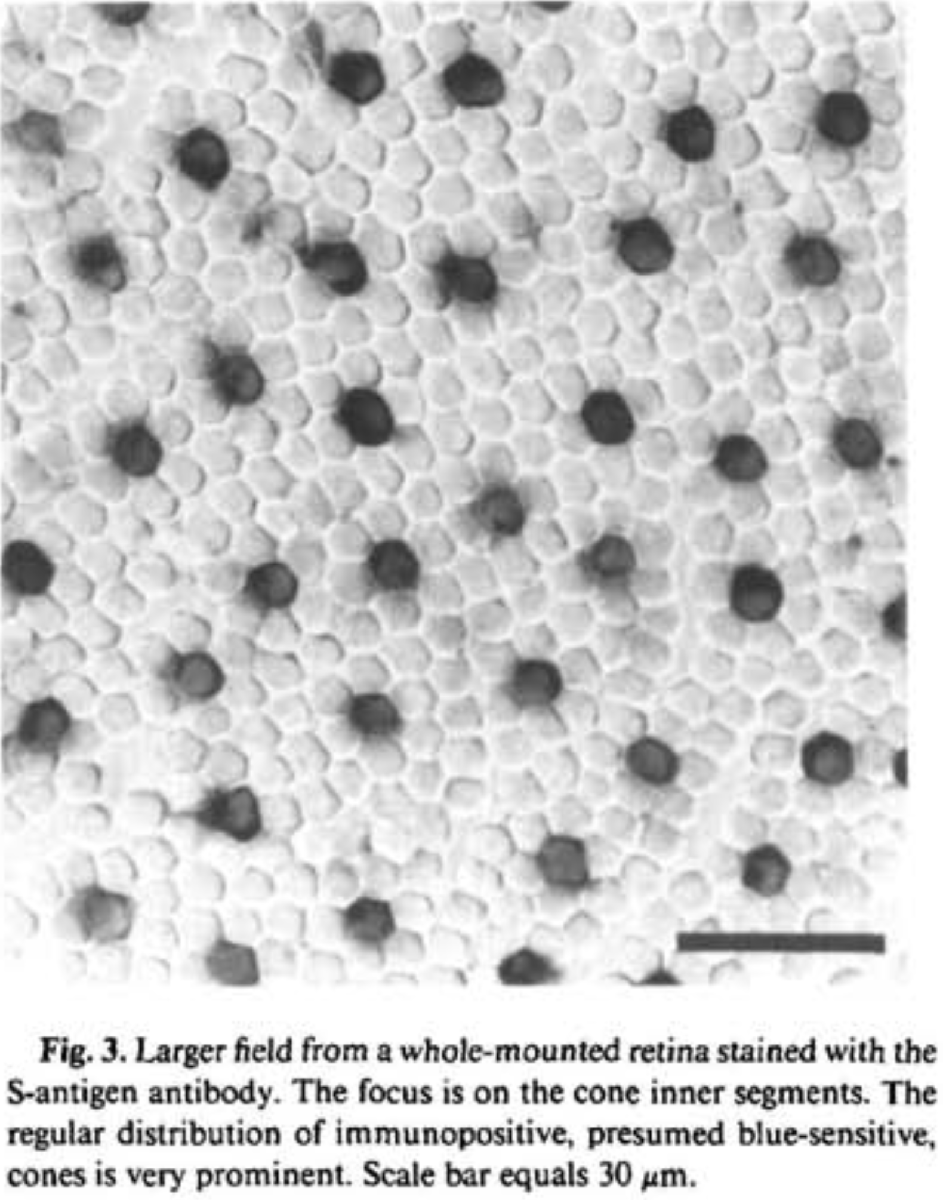

# **Step 2.** Create and visualize a custom TreeShrew cone mosaic

% Generate a custom mosaic with:
% - field of view of 4x4 degs
% - L-and S-cones ratio: 60/40
% - separation between neighboring cones: 10 microns
% - cone inner segment diameter: 6 microns
% - integration time: 50 mseconds
theConeMosaic = coneMosaicTreeShrewCreate(...
    umPerDegOnTreeShrewRetina, ...
    'spatialDensity', [0 0.6 0 0.4],...
    'sConeMinDistanceFactor', [], ...
    'customLambda', 10, ...
    'customInnerSegmentDiameter', 6, ...
    'fovDegs', [4.0 4.0], ...
    'integrationTime', 50/1000);


Resampling grid. Please wait ... Done !
Will not change the S-cone density.
Scones before making an S-cone free central patch: 427
Scones after making an S-cone free central patch: 427 (added Lcones:0, added Mcones:0)
Will not adjust the minimum S-cone separation
.

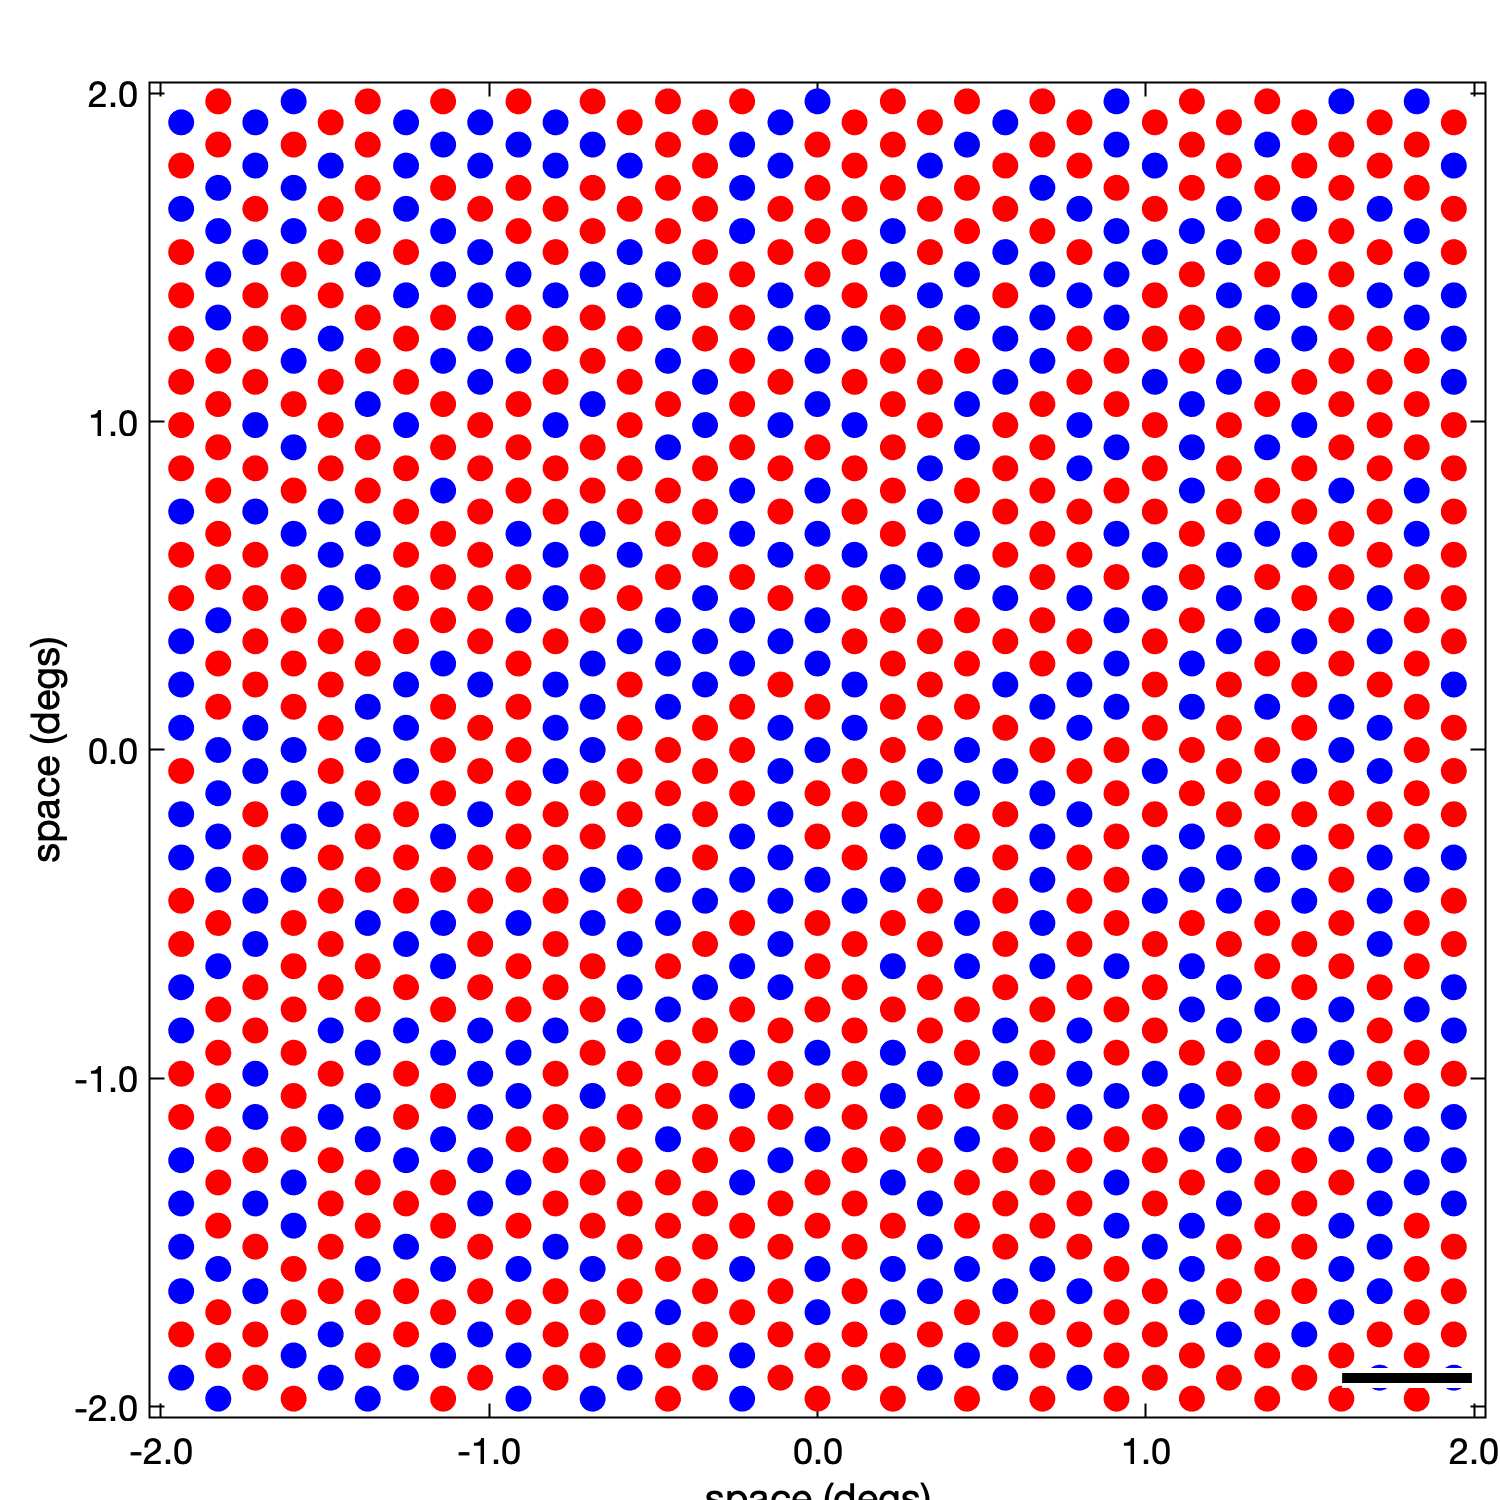


% Visualize the mosaic along with a 30-micron scale bar
theConeMosaic.visualizeGrid(...
    'backgroundColor', [1 1 1], ...
    'generateNewFigure', true, ...
    'scaleBarLengthMicrons', 30, ...
    'ticksInVisualDegs', true);


% Display some info
theConeMosaic.displayInfo();


Mosaic info:
                                      Size (microns): 306.0 (w) x 306.0 (h)
                                           FOV (deg): 4.03 (w) x 4.03 (h)
                                   Retinal coverages: 0.322 (aperture) x 0.895 (geometric)
                              Grid resampling factor: 7
                   Cone geometric aperture (microns): 8.86 (w) x 8.86 (h), diameter: 10.00
             Cone light colleting aperture (microns): 5.32 (w) x 5.32 (h), diameter: 6.00

                     Cone geometric area (microns^2): 78.5398 
               Cone light colleting area (microns^2): 28.2743
                                    Rectangular grid: 39 cols x 39 rows
                                      Resampled grid: 1071 cols x 1071 rows
                                         Total cones: 1147041
                                        Active cones: 1067
                                            L- cones: 640 (59.981%)
                                            M

# **Step 3. **Visualize the TreeShrew cone absorbance spectra

The absorbance, A, of a material, is defined as  the logarithm of the ratio of the radiance incident to the material to the radiance transmitted by the material: $A={\mathrm{log}}_{10} \left(\frac{\Phi_i }{\Phi_t }\right)$ . Spectral absorbance is the absorbance as a function of wavelength. Below the plot the axial spectral absorbance of the  tree shrew pigments. 

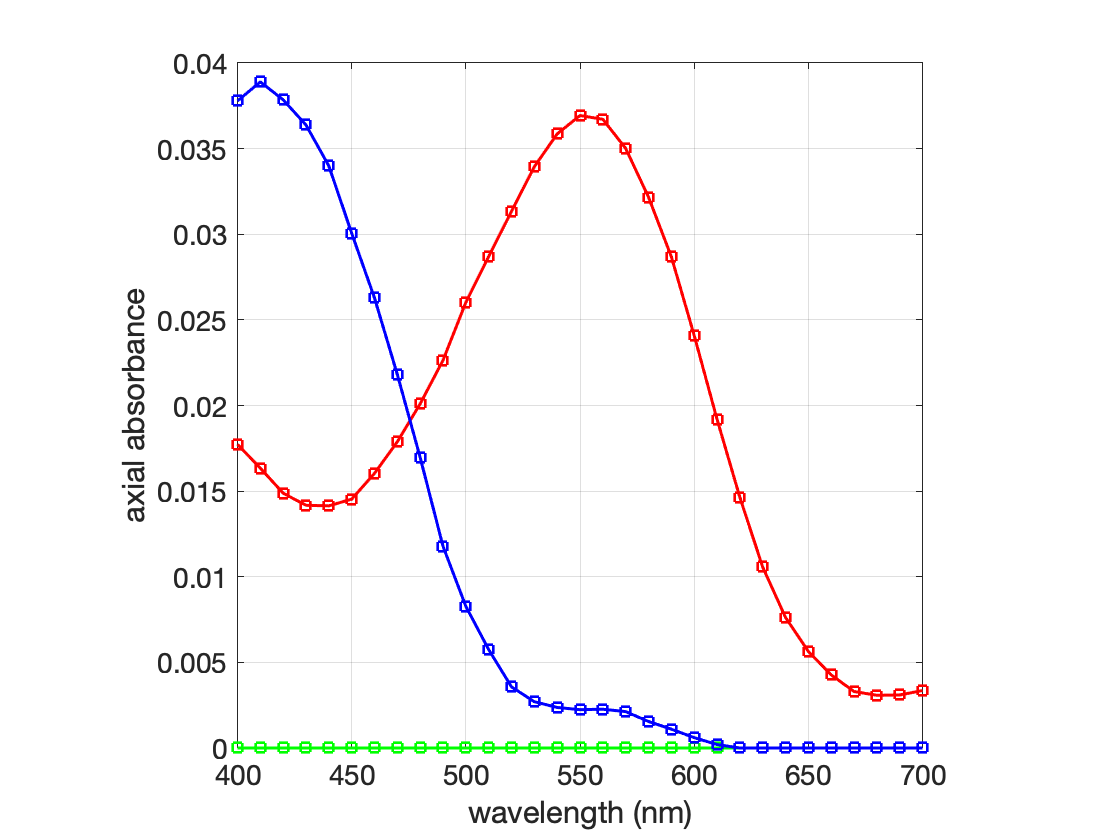

ans =     0.0369         0    0.0389


% Retrieve the axial spectral absorbance specta
wavelength = theConeMosaic.wave;
thePigments = theConeMosaic.pigment;
theAxialAbsorbanceSpectra = bsxfun(@times, thePigments.absorbance, thePigments.opticalDensity');

% Plot them
figure()
plotActionSpectra(wavelength, theAxialAbsorbanceSpectra, 'axial absorbance', '');

For reference, the L- and S-cone absorbance spectra measured by Petry and Harosi in 1989, are displayed below. The absorbance spectra of the TreeShrew photopigment object are extracted from these measurements.

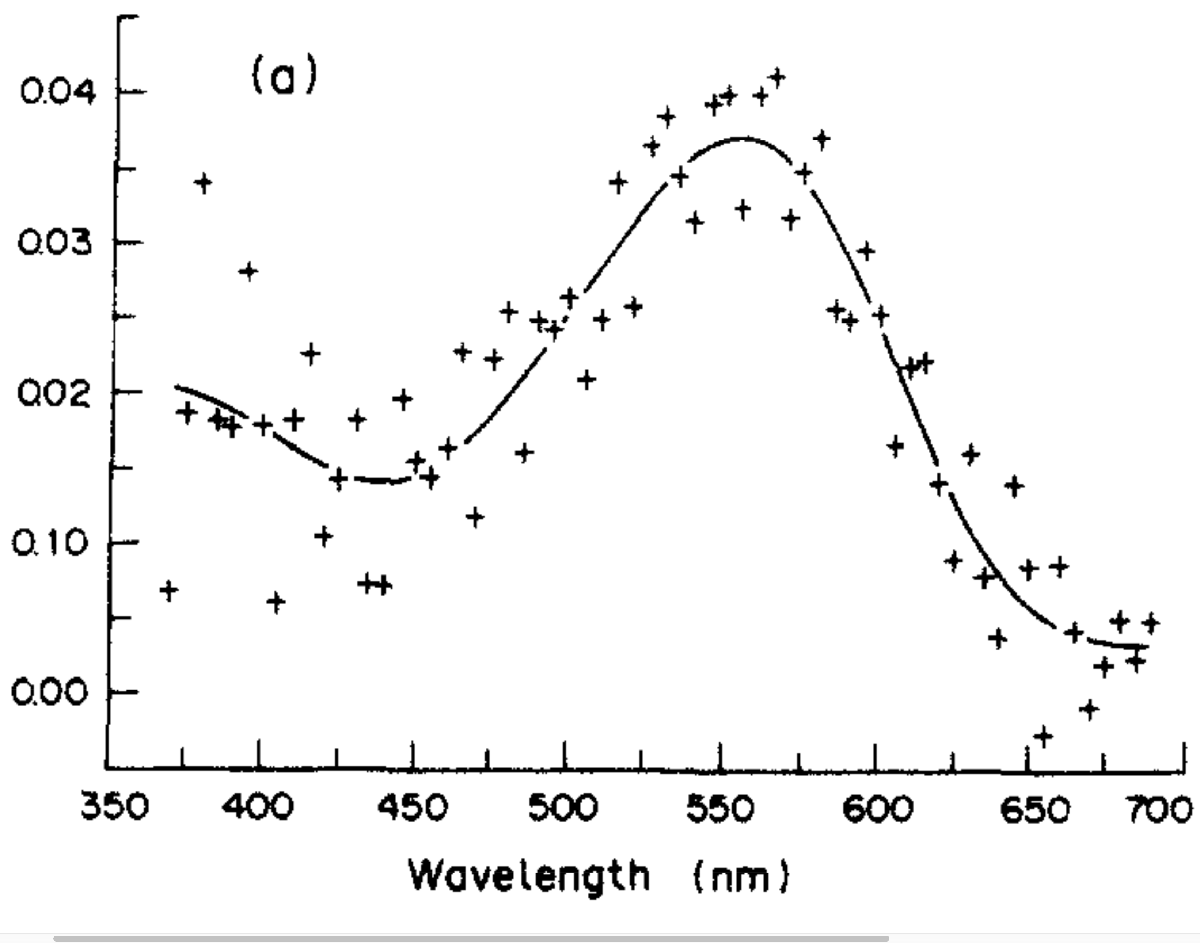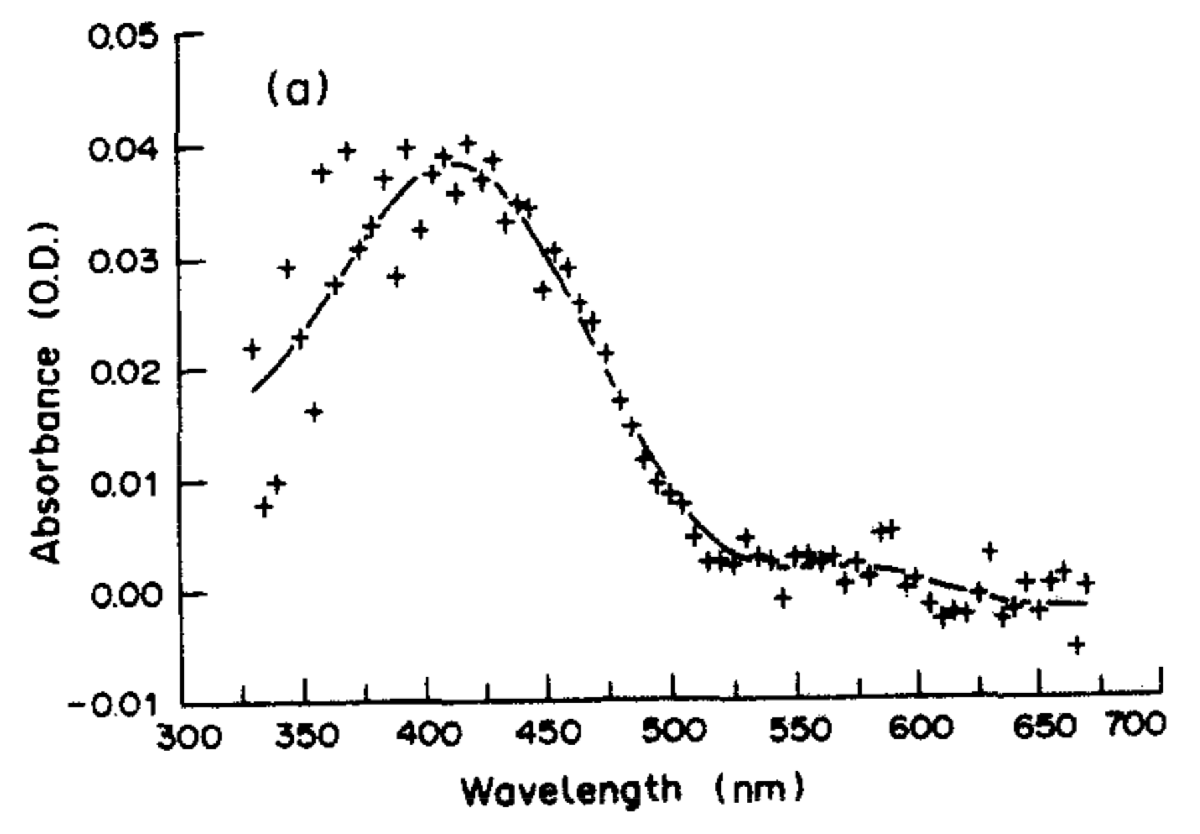

# **Step 4.** Visualize the TreeShrew cone fundamentals

The cone fundamentals are the normalized absorptance spectra, where absorptance is the ratio of the absorbed photons to the incident photons. Since $\Phi_i =\Phi_t +\Phi_a$ where $\Phi_a$denotes the absorbed photons, it can be proven that $\frac{\Phi_a }{\Phi_i }=1-{10}^{\left(-A\right)}$, where $A$ is the axial absorbance. 

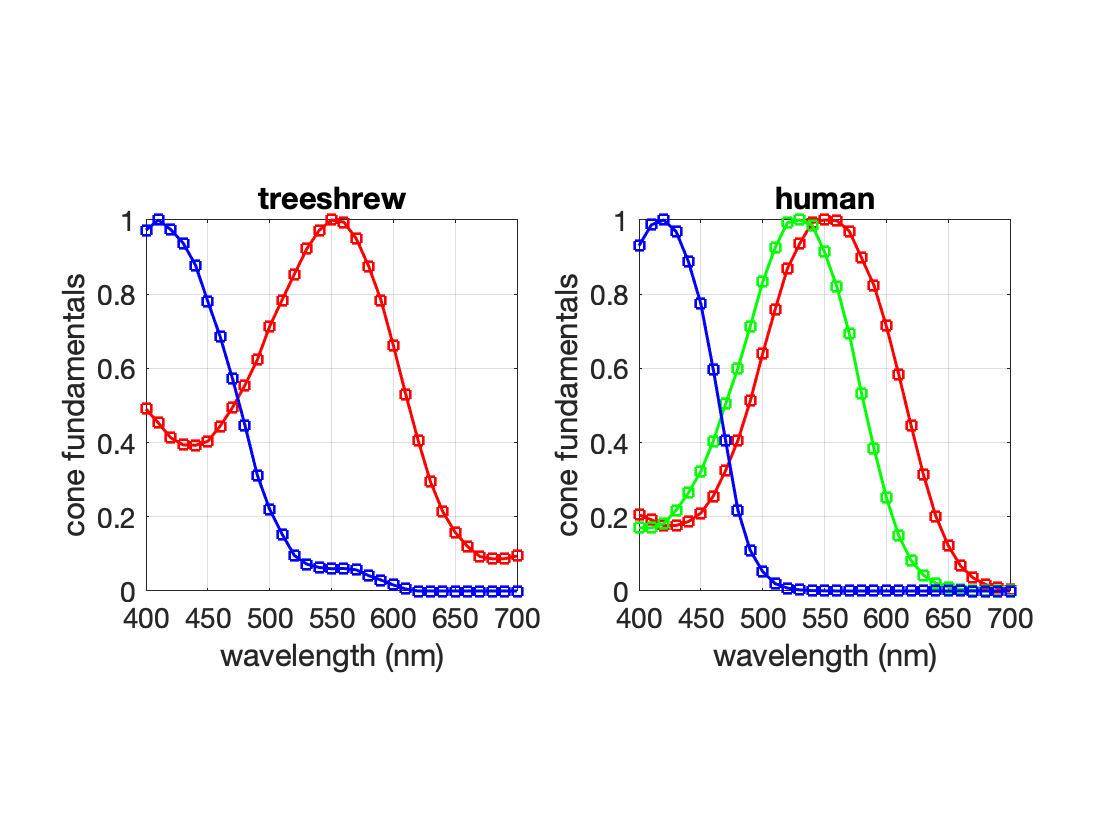

% Retrieve absorptances
absorptances = thePigments.absorptance;
% Cone fundemantals are the normalized absorptances
coneFundamentals = bsxfun(@rdivide, absorptances, max(absorptances));
% Plot them
figure()
subplot(1,2,1)
plotActionSpectra(wavelength, coneFundamentals, 'cone fundamentals', 'treeshrew');
% plot human cone fundamentals
subplot(1,2,2)
theHumanMosaic = coneMosaic();
plotActionSpectra(theHumanMosaic.wave, theHumanMosaic.pigment.quantaFundamentals, 'cone fundamentals', 'human');

Note that the treesheew cone fundamentals are more broadly tuned than their human counterparts. Also note that these cone fundamentals do not include pre-retinal absorption by the lens only by the macular pigment, and that in the treeshrew model there is zero macular pigment absorption.

function plotActionSpectra(w, a, aName, tName)
    plot(w, a(:,1), 'rs-', 'LineWidth', 1.5); hold on;
    plot(w, a(:,2), 'gs-','LineWidth', 1.5);
    plot(w, a(:,3), 'bs-','LineWidth', 1.5);
    axis 'square'
    set(gca, 'XTick', [400:50:700]);
    grid on
    xlabel('wavelength (nm)')
    ylabel(aName)
    title(tName)
    set(gca, 'FontSize', 14)
end